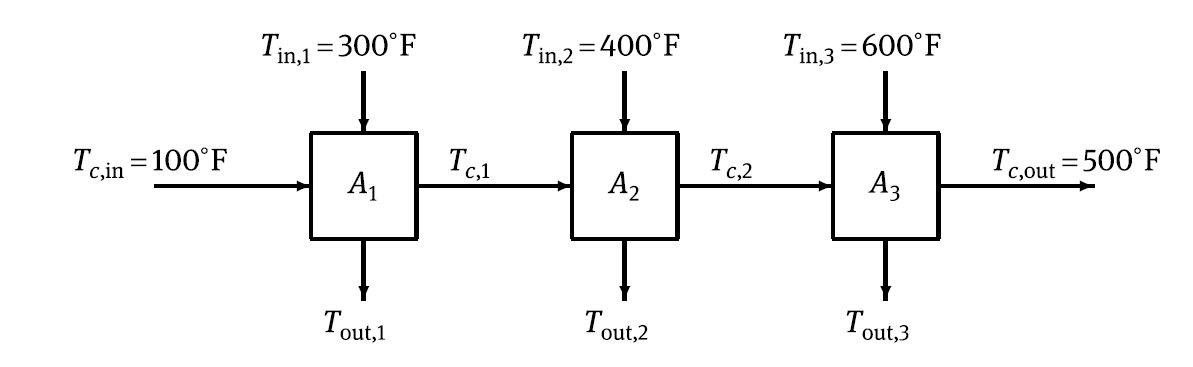

In order to save energy, three heaters are expected such that the sum of the heated areas A1 + A2 + A3 is minimized

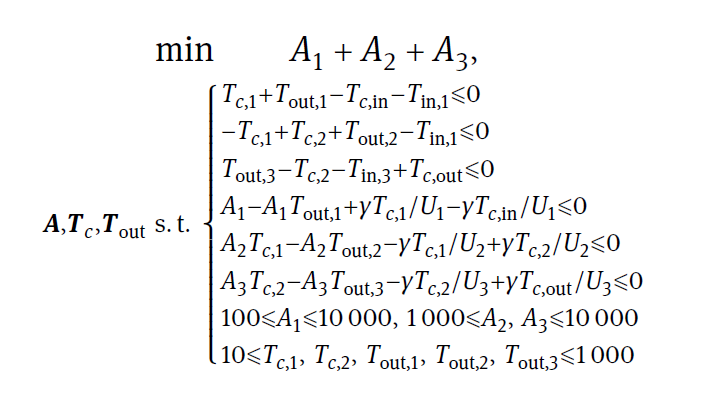

where γ = 105, U1 = 120, U2 = 80, and U3 = 40.

% parameters
gama=1e5; U=[120,80,40]; 
Tcin=100; T1in=300; T2in=400; T3in=600; Tcout=500;

% inital guess
Surf0 = [150, 150, 1000];        % [S1,S2,S3]
TC0   = [200, 300      ];        % [S4,S5]
Tout0 = [200, 300, 500 ];        % [S6,S7,S8]
x0 = [Surf0, TC0, Tout0];

% problem formulation

% HX surface is described as 'S', bc 'A' is used as inequlity matrix
fun = @(S)S(1)+S(2)+S(3)

fun = function_handle with value:
    @(S)S(1)+S(2)+S(3)



% S  1 2 3 4 5 6 7 8
A = [0,0,0,1,0,1,0,0;
     0,0,0,-1,1,0,1,0;
     0,0,0,0,-1,0,0,1];
b = [Tcin+T1in;
     T1in;
     T3in-Tcout];

Aeq = [];
beq = [];

lb = [100 , 1000 , 1000 , 10  , 10  , 10  , 10  , 10  ];
ub = [1000, 10000, 10000, 1000, 1000, 1000, 1000, 1000];
%      S1    S2     S3     S4    S5    S6    S7    S8

nonlcon = @nonlconFun;
%nonlcon = [];
options = optimoptions('fmincon','Display','iter');

x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       9    2.151980e+03    2.998e+05    3.767e+00
    1      18    2.153733e+03    2.995e+05    3.767e+00    1.123e+00
    2      27    2.171555e+03    2.975e+05    3.767e+00    1.145e+01
    3      36    3.816894e+03    1.521e+05    4.044e+00    1.056e+03
    4      45    3.841109e+03    1.514e+05    4.102e+00    1.532e+01
    5      54    3.851361e+03    1.509e+05    4.106e+00    8.741e+00
    6      63    5.360493e+03    1.035e+05    6.704e+00    1.361e+03
    7      72    7.686589e+03    4.147e+04    1.373e+01    2.076e+03
    8      81    8.136212e+03    0.000e+00    1.512e+01    4.090e+02
    9      90    8.131787e+03    0.000e+00    1.511e+01    3.445e+00
   10      99    8.105901e+03    0.000e+00    1.506e+01    1.757e+01
   11    

function [c,ceq] = nonlconFun(S)

    gama=1e5; U=[120,80,40]; 
    Tcin=100; T1in=300; T2in=400; T3in=600; Tcout=500;

    c = [ S(1)-S(1)*S(6)+gama*S(4)/U(1)-gama*Tcin/U(1);
          S(2)*S(4)-S(2)*S(7)-gama*S(4)/U(2)+gama*S(5)/U(2);
          S(3)*S(5)-S(3)*S(8)-gama*S(5)/U(3)+gama*Tcout/U(3)];
  
  ceq = [];
end